# WBE performance by state

Analysis of RT-PCR quantified SARS-CoV-2 viral loads in wastewater samples from college campuses across 21 of the 32 states of Mexico

## Importing MARTEC registries clustered by state

opts = delimitedTextImportOptions("NumVariables", 8, "Encoding", "UTF-8");

% Specify range and delimiter
opts.DataLines = [2, Inf];
opts.Delimiter = ",";

% Specify column names and types
opts.VariableNames = ["Semana", "Campus", "Ncampus", "Edificio", "Sitio", "Estado", "Nestado", "Copias_L"];
opts.VariableTypes = ["double", "categorical", "double", "double", "categorical", "categorical", "double", "double"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Specify variable properties
opts = setvaropts(opts, ["Campus", "Sitio", "Estado"], "EmptyFieldRule", "auto");

% Import the data
MARTEC_Datos_Estados = readtable("/MATLAB Drive/Analisis de datos MARTEC/MARTEC_Datos_Estados.csv", opts)

MARTEC_Datos_Estados = 9690x8 table
    Semana        Campus        Ncampus    Edificio          Sitio               Estado        Nestado     Copias_L 
    ______    ______________    _______    ________    __________________    ______________    _______    __________

       5      Aguascalientes       1          6        LIFE                  AGUASCALIENTES       1                0
       7      Aguascalientes       1          6        LIFE                  AGUASCALIENTES       1       1.3408e+05
       8      Aguascalientes       1          1        Colector principal    AGUASCALIENTES       1       1.4648e+06
       9      Aguascalientes       1          6        LIFE                  AGUASCALIENTES       1       

clear opts

## Importing clinical reports

opts = delimitedTextImportOptions("NumVariables", 35, "Encoding", "UTF-8");

% Specify range and delimiter
opts.DataLines = [2, Inf];
opts.Delimiter = ",";

% Specify column names and types
opts.VariableNames = ["Ano", "Semana", "Dia", "AGUASCALIENTES", "BAJACALIFORNIA", "BAJACALIFORNIASUR", "CAMPECHE", "CHIAPAS", "CHIHUAHUA", "DISTRITOFEDERAL", "COAHUILA", "COLIMA", "DURANGO", "GUANAJUATO", "GUERRERO", "HIDALGO", "JALISCO", "MEXICO", "MICHOACAN", "MORELOS", "NAYARIT", "NUEVOLEON", "OAXACA", "PUEBLA", "QUERETARO", "QUINTANAROO", "SANLUISPOTOSI", "SINALOA", "SONORA", "TABASCO", "TAMAULIPAS", "TLAXCALA", "VERACRUZ", "YUCATAN", "ZACATECAS"];
opts.VariableTypes = ["double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Import the data
ConcentradoCasosDiarios = readtable("/MATLAB Drive/Analisis de datos MARTEC/Concentrado casos diarios.csv", opts)

ConcentradoCasosDiarios = 541x35 table
    Ano     Semana    Dia    AGUASCALIENTES    BAJACALIFORNIA    BAJACALIFORNIASUR    CAMPECHE    CHIAPAS    CHIHUAHUA    DISTRITOFEDERAL    COAHUILA    COLIMA    DURANGO    GUANAJUATO    GUERRERO    HIDALGO    JALISCO    MEXICO    MICHOACAN    MORELOS    NAYARIT    NUEVOLEON    OAXACA    PUEBLA    QUERETARO    QUINTANAROO    SANLUISPOTOSI    SINALOA    SONORA    TABASCO    TAMAULIPAS    TLAXCALA    VERACR

clear opts

load("Heatmap_MARTEC.mat"); %Loads the color map for the resulting heatmap

## Calculates the weekly average of new daily cases for each state

ConcentradoCasosDiarios(:,["Ano","Dia"])=[];
VarEst=ConcentradoCasosDiarios.Properties.VariableNames;
Estados=ConcentradoCasosDiarios.Properties.VariableNames(2:end);
Semanas=[1:1:78]';
Casos=zeros(78,32);

for i=1:1:78
    DatoSem=table2array(ConcentradoCasosDiarios(ConcentradoCasosDiarios.Semana==i,2:end));
    PromSem=mean(DatoSem,1);
    Casos(i,:)=PromSem;
end

Casos=[Semanas Casos];
CasosDiarios=array2table(Casos,"VariableNames",VarEst)

CasosDiarios = 78x33 table
    Semana    AGUASCALIENTES    BAJACALIFORNIA    BAJACALIFORNIASUR    CAMPECHE    CHIAPAS    CHIHUAHUA    DISTRITOFEDERAL    COAHUILA    COLIMA    DURANGO    GUANAJUATO    GUERRERO    HIDALGO    JALISCO    MEXICO    MICHOACAN    MORELOS    NAYARIT    NUEVOLEON    OAXACA    PUEBLA    QUERETARO    QUINTANAROO    SANLUISPOTOSI    SINALOA    SONORA    TABASCO    TAMAULIPAS    TLAXCALA    VERACRUZ    YUCATAN    ZACATECAS<

## Summarizes sampling for each state

Resumen=[];
for i=1:1:32
    DatoEstado=MARTEC_Datos_Estados(MARTEC_Datos_Estados.Nestado==i,:);
    Muestras=size(DatoEstado,1);
    SemMuestreo=size(unique(DatoEstado.Semana),1);
    EdMuestreo=size(unique(DatoEstado.Edificio),1);
    NumEstado=i;
    Resumen(i,:)=[NumEstado Muestras SemMuestreo EdMuestreo];
end
Resumen=[Resumen];
Resumen=array2table(Resumen,"VariableNames",["State" "Total samples" "Weekly samplings" "Buildings"]);
Resumen(Resumen.("Total samples")==0,:)=[] %Clears empty data points

Resumen = 20x4 table
    State    Total samples    Weekly samplings    Buildings
    _____    _____________    ________________    _________

      1           258                61               9    
      5            98                59               4    
      6           879                61              14    
      7           477                61              11    
      8           855                57              17    
     11           987                61              17    
     13           134                59               6    
     14           658                60              28    
     15           610                55              18    
     16           112                58               7    
     17            57                53               5    
     19          2006                61              44    
  

## Evaluates correlation between viral loads in wastewater samples clustered by state and clinical COVID-19 incident reports

EvalPearson=[];
Pearsons=[];
InfoEstado=[];
for j=1:1:32
InfoEstado=[];
DatoEstado=sortrows(MARTEC_Datos_Estados(MARTEC_Datos_Estados.Nestado==j,:),"Semana","ascend");
if size(DatoEstado,1)==0
        continue
end
TotEd=double(table2array(Resumen(Resumen.State==j,"Buildings")));
for i=1:1:78
    DatoSemEstado=DatoEstado(DatoEstado.Semana==i,:);
    if size(DatoSemEstado,1)>0
        Muestras=size(DatoSemEstado,1);
        XMuestreo=Muestras/TotEd;
        PromCopias=mean(DatoSemEstado.Copias_L,1);
        MaxCopias=max(DatoSemEstado.Copias_L);
        MPositivas=sum(DatoSemEstado.Copias_L>0);
        XMuestrasPos=MPositivas/Muestras;
        XEdPositivos=MPositivas/TotEd;
        InfoEstado(i,:)=[i Muestras XMuestreo PromCopias MaxCopias MPositivas XMuestrasPos XEdPositivos];
    else
        Muestras=0;
        XMuestreo=0;
        PromCopias=0;
        MaxCopias=0;
        MPositivas=0;
        XMuestrasPos=0;
        XEdPositivos=0;
        InfoEstado(i,:)=[i Muestras XMuestreo PromCopias MaxCopias MPositivas XMuestrasPos XEdPositivos];
    end 
end
CasosEstado=table2array(CasosDiarios(:,j+1));
InfoEstado=array2table([InfoEstado CasosEstado],"VariableNames",["Week","Total_Samples","%_Coverage", "Avg_Copies", "Max_Copies", "Positive_Samples", "Positive_Rate", "Positive_Building_Rate", "Cases"]);
InfoEstado(InfoEstado.("%_Coverage")==0,:)=[]; %Clears empty data points
[CPro,PvPro]=corrcoef(InfoEstado.("Avg_Copies"),InfoEstado.("Cases")); %Correlation by average copies
CPro=CPro(2,1);
PvPro=PvPro(2,1);
[CMax,PvMax]=corrcoef(InfoEstado.("Max_Copies"),InfoEstado.("Cases")); %Correlation by maximum copies
CMax=CMax(2,1);
PvMax=PvMax(2,1);
[CMue,PvMue]=corrcoef(InfoEstado.("Positive_Rate"),InfoEstado.("Cases")); %Correlation by positive sample rate
CMue=CMue(2,1);
PvMue=PvMue(2,1);
[CEd,PvEd]=corrcoef(InfoEstado.("Positive_Building_Rate"),InfoEstado.("Cases")); %Correlation by positive building rate
CEd=CEd(2,1);
PvEd=PvEd(2,1);
Cobertura=mean(InfoEstado.("%_Coverage"),1);
DEstCobertura=std(InfoEstado.("%_Coverage"),1);
SemConsideradas=size(InfoEstado,1);
Pearsons=[j TotEd SemConsideradas Cobertura DEstCobertura CPro PvPro CMax PvMax CMue PvMue CEd PvEd];
EvalPearson(j,:)=Pearsons;
Pearsons=[];
end
Cols=["State", "Buildings","Weekly samples","Avg coverture","St. Dev. Coverture", "Corr_AvgCopies","p1","Corr_MaxCopies","p2","Corr_PosRate","p3","Corr_PosBuiRate","p4"];
EvalPearson=array2table(EvalPearson,"VariableNames",Cols);
EvalPearson(EvalPearson.Buildings==0,:)=[] %Clears empty data points

EvalPearson = 20x13 table
    State    Buildings    Weekly samples    Avg coverture    St. Dev. Coverture    Corr_AvgCopies        p1        Corr_MaxCopies        p2        Corr_PosRate        p3        Corr_PosBuiRate        p4    
    _____    _________    ______________    _____________    __________________    ______________    __________    ______________    __________    ____________    __________    _______________    __________

      1          9              61             0.46995               0.187             0.10694          0.41202      

## Creates a matrix of states were SARS-CoV-2 was successfully detected

HResumenEstado=[];
NoEstado=[];
k=1;
for i=1:1:32
    HEstado=sortrows(MARTEC_Datos_Estados(MARTEC_Datos_Estados.Nestado==i,:),"Semana","ascend");
    if size(HEstado,1)==0;
        HResumenEstado(i,:)=-1;
        NoEstado(k)=i;
        k=k+1;
        continue
    end
    for j=1:1:78
        HSemEstado=HEstado(HEstado.Semana==j,:);
        if size(HSemEstado,1)==0;
            HResumenEstado(i,j)=-1;
        else
            if max(HSemEstado.Copias_L)==0;
                HResumenEstado(i,j)=0;
            else
                HResumenEstado(i,j)=1;
            end
        end
    end
end
HResumenEstado(:,1:4)=[];
HResumenEstado(NoEstado,:)=[];

## Builds the heatmap by state

Estados=unique(MARTEC_Datos_Estados.Estado);
Estados(Estados=="Unidentified")=[];

Estados = 20x1 categorical array
     AGUASCALIENTES 
     CHIAPAS 
     CHIHUAHUA 
     COAHUILA 
     DISTRITO FEDERAL 
     GUANAJUATO 
     HIDALGO 
     JALISCO 
     MEXICO 
     MICHOACAN 
     MORELOS 
     NUEVO LEON 
     PUEBLA 
     QUERETARO 
     SAN LUIS POTOSI 
     SINALOA 
     SONORA 
     TAMAULIPAS 
     VERACRUZ 
     ZACATECAS 


HeatCampus=heatmap(HResumenEstado,"YLabel","State", "YDisplayLabels", Estados, "XDisplayLabels", [5:1:78],"XLabel","Week","Title","SARS-CoV-2 detection per state","Colormap",Heatmap_MARTEC,"FontSize",8)

HeatCampus =   HeatmapChart (SARS-CoV-2 detection per state) with properties:

        XData: {74x1 cell}
        YData: {20x1 cell}
    ColorData: [20x74 double]

  Show all properties


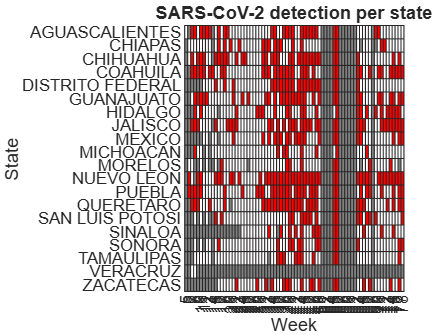

colorbar off